# Challenge report Part 1

F1013B

clc; clear; close all;

## Load files and data

url_charge = "https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1013B/Charge.csv";
url_discharge = "https://raw.githubusercontent.com/cararm4073/tec-archive/refs/heads/main/university/EF26/F1013B/Discharge.csv";

Load data to matlab

charge_data = readtable(url_charge);
discharge_data = readtable(url_discharge);

Set variables for charge and discharge

t_charge = charge_data{:,1};    % time
y_charge = charge_data{:,2};    % voltage values

t_discharge = discharge_data{:,1};
y_discharge = discharge_data{:,2};

## Raw data - Charge

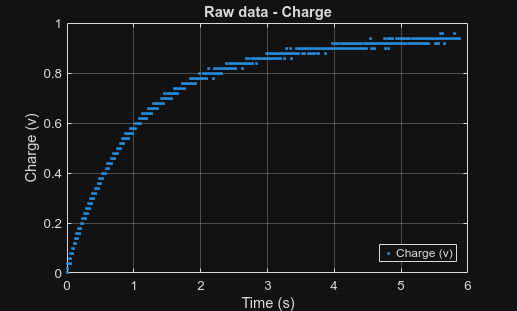

figure( 'Name', 'Raw data - Charge' );
plot(t_charge,y_charge,'.');
legend('Charge (v)', 'Location', 'SouthEast');
title("Raw data - Charge")
xlabel("Time (s)")
ylabel("Charge (v)")
grid on

## Raw data - Discharge

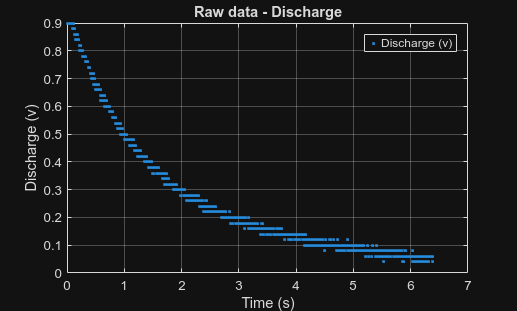


figure( 'Name', 'Raw data - Discharge' );
plot(t_discharge,y_discharge,'.');
legend('Discharge (v)', 'Location', 'NorthEast');
title("Raw data - Discharge")
xlabel("Time (s)")
ylabel("Discharge (v)")
grid on

## Curve fit - Charge

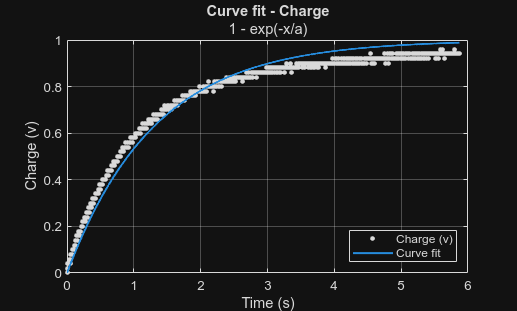

%CREATEFIT(T_CHARGE,Y_CHARGE)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input: t_charge
%      Y Output: y_charge
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 04-Apr-2026 02:43:18


%% Fit: 'Charge'.
[xData, yData] = prepareCurveData( t_charge, y_charge );

% Set up fittype and options.
ft = fittype( '1-exp(-x/a)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = 0.442678269775446;

% Fit model to data.
[fit_charge, gof_charge] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'Curve fit - Charge' );
h = plot( fit_charge, xData, yData );
legend( h, 'Charge (v)', 'Curve fit', 'Location', 'SouthEast', 'Interpreter', 'none' );
title("Curve fit - Charge")
subtitle("1 - exp(-x/a)")
xlabel("Time (s)", "Interpreter", "none")
ylabel("Charge (v)", "Interpreter", "none")
grid on

## Curve fit - Discharge

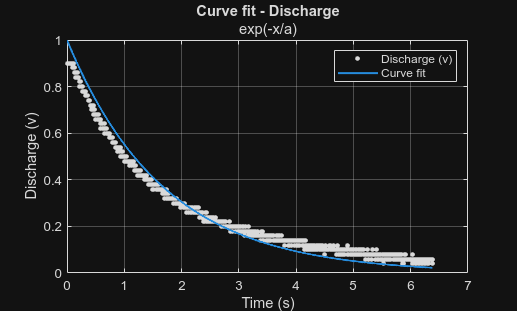

%CREATEFIT(T_DISCHARGE,Y_DISCHARGE)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input: t_discharge
%      Y Output: y_discharge
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 04-Apr-2026 02:54:05

%% Fit: 'Discharge'.
[xData, yData] = prepareCurveData( t_discharge, y_discharge );

% Set up fittype and options.
ft = fittype( 'exp(-x/a)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = 0.0759666916908419;

% Fit model to data.
[fit_discharge, gof_discharge] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'Curve fit - Discharge' );
h = plot( fit_discharge, xData, yData );
legend( h, 'Discharge (v)', 'Curve fit', 'Location', 'NorthEast', 'Interpreter', 'none' );
title("Curve fit - Discharge")
subtitle("exp(-x/a)")
xlabel("Time (s)", "Interpreter", "none")
ylabel("Discharge (v)", "Interpreter", "none")
grid on

## Time constant (τ) calculation

tau_charge = fit_charge.a;
tau_discharge = fit_discharge.a;


disp(['Time constant (τ) of charge: ', num2str(tau_charge), ' s']);

Time constant (τ) of charge: 1.3114 s


disp(['Time constant (τ) of discharge: ', num2str(tau_discharge), ' s']);

Time constant (τ) of discharge: 1.6849 s
